# Intraday Pairs trading

This demo shows how functionality within Econometric Toolbox can be used to identify and calibrate a simple, intraday pairs trading strategy.

## Load intraday data from a database

We will download intraday data for Brent Crude (LCO) from our database. We will also download data corresponding to West Texas Intermediate (WTI).

% getfromDB = false; % read either from the Micosoft Access databse (true) or from Excel files (false)
% 
% if getfromDB
%     LCO = getMinuteDataFromDB('LCO');
%     WTI = getMinuteDataFromDB('WTI');
% else
%     LCO = readtable('LCO.xlsx');
%     WTI = readtable('WTI.xlsx');
%     
%     % convert to numeric array without the column ID
%     LCO = LCO{:,2:end};
%     WTI = WTI{:,2:end};
% end
LCO = readtimetable('brent-crude-oil-prices-10-year-daily-chart.csv');

Error using readtimetable (line 188)
Unable to find or open 'brent-crude-oil-prices-10-year-daily-chart.csv'. Check the path and filename or file permissions.

LCO.xldate = exceltime(LCO.date);
LCO = LCO(:,{'xldate','value'});
WTI = readtimetable('wti-crude-oil-prices-10-year-daily-chart.csv');
WTI.xldate = exceltime(WTI.date);

TT = rmmissing(synchronize(LCO,WTI));

WTI = TT(:,{'xldate_WTI','value_WTI'});
LCO = TT(:,{'xldate_LCO','value_LCO'});
LCO = LCO{:,1:end}; LCO(:,4) = LCO(:,2);
WTI = WTI{:,1:end}; WTI(:,4) = WTI(:,2);

pairsChart(LCO, WTI)

These two time series have historically tracked each other, but since December 2010, LCO has consistently traded higher than WTI.  It would seem that a pairs trading strategy would not work in 2011, but if we are willing to actively recalibrate our model on an intraday basis, we may find profitable opportunities.

Let's focus on the last 11 days' of data:

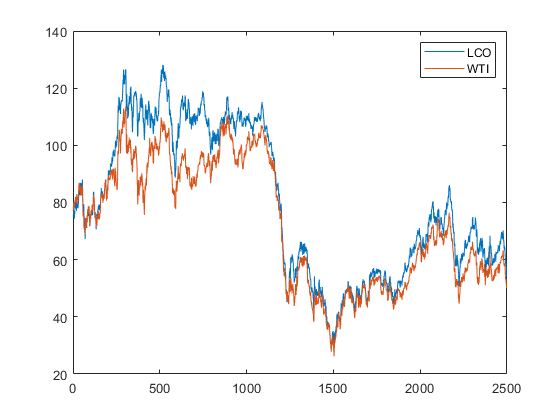

series = [LCO(:, 4) WTI(:, 4)];
plot(series)
legend('LCO','WTI')

## The cointegration test framework

Econometrics Toolbox supports both the Engle-Granger and the Johansen cointegration frameworks. Engle-Granger is the older model, and Johansen is particularly useful for analyzing more than two time series at a time. We will use Engle-Granger for our trading model.

First, we note that the last 11 days are not cointegrated as a whole

egcitest(series)

ans = logical
   1


A zero indicates failure to reject the null hypothesis that no  cointegrating relationship exists.

Even so, there are smaller windows of time where a cointegrating relationship does exist.

[h, ~, ~, ~, reg1] = egcitest(series(:, :));
display(h)

h = logical
   1


The test estimates the coefficients of the cointegrating regression as well as the residuals and the standard errors of the residuals: all useful information for any pairs trading strategy.

display(reg1)

reg1 = struct with fields:
       num: 2497
      size: 2497
     names: {2×1 cell}
     coeff: [2×1 double]
        se: [2×1 double]
       Cov: [2×2 double]
    tStats: [1×1 struct]
     FStat: [1×1 struct]
       yMu: 79.7172
    ySigma: 25.8463
      yHat: [2497×1 double]
       res: [2497×1 double]
    DWStat: 0.0430
       SSR: 1.5919e+06
       SSE: 7.5521e+04
       SST: 1.6674e+06
       MSE: 30.2688
      RMSE: 5.5017
       RSq: 0.9547
      aRSq: 0.9547
        LL: -7.7996e+03
       AIC: 1.5603e+04
       BIC: 1.5615e+04
       HQC: 1.5607e+04


## The pairs trading strategy

The following function describes our pairs strategy.

edit pairs

We may test this strategy as we do our other rules:

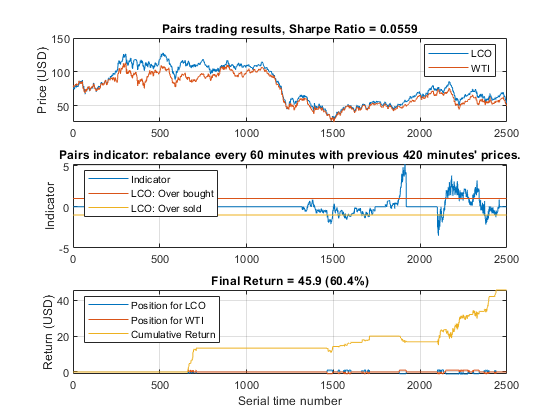

pairs(series, 420, 60)

Note that this strategy will not trade if the most recent minutes do not show signs of cointegration and that the size of the long/short positions are dynamically scaled with the volatility of the cointegrating relationship.  Many other customizations can be made.

We can use our existing parameter sweep framework to identify the best combination of calibration window and rebalancing frequency.

p = gcp('nocreate');
if isempty(p)
    p = parpool('local');
end

window = 120:60:420;
freq   = 10:10:60;
range = {window, freq};

annualScaling = sqrt(250*7*60);
cost = 0.01;

pfun = @(x) pairsFun(x, series, annualScaling, cost);

tic
[~,param] = parameterSweep(pfun,range);
toc

Elapsed time is 34.901177 seconds.


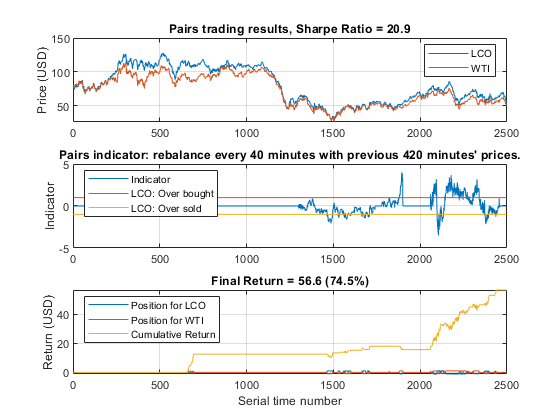

pairs(series, param(1), param(2), 1, annualScaling, cost)

Despite the fact that these historically-tracking time series have diverged, we can still create a profitable pairs trading strategy by frequently recalibrating.

*Copyright 2020, The MathWorks, Inc.*